# 1-8-2018 - Multisubject Anova Analysis with general linear mixed model

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
anovaStimLevel = [];
%answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

answer = 'raw';
% exclude playback for now
% which
conf = 'CSNESiteVisit';
%conf = 'NeuroModulation';
%conf = 'NeuroModulationV2';

%conf = 'NeuroModulationV3';
%conf = 'NeuroModulationV4';
% 6/17/_2016 try neuromdoulation
for i = 2:length(SIDS)-4
    sid = SIDS{i};
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
            typeCell = {'180'};
            stimLevel = 2500;
            
        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            stimLevel = 3000;
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
            stimLevel = 3500;
            
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
            stimLevel = 750;
            
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            stimLevel = 750;
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            stimLevel = 1750;
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'0b5a2eepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            stimLevel = 1750;
            
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim',conf,'0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            stimLevel = 1750;
            
            
    end
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{betaChan});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = [];
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                
                
                if (strcmp(conf,'NeuroModulation') | strcmp(conf,'NeuroModulationV2')| strcmp(conf,'NeuroModulationV4')  | strcmp(conf,'NeuroModulationV3')) & strcmp(answer,'zscore')
                    tB = [tB tempBase'];
                    t1 = [t1 tempResp1'];
                    t2 = [t2 tempResp2'];
                    t3 = [t3 tempResp3'];
                else
                    tB = [tB tempBase];
                    t1 = [t1 tempResp1];
                    t2 = [t2 tempResp2];
                    t3 = [t3 tempResp3];
                end
                
                lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
                vecType = repmat(typeCell{i},lengthType,1);
                vecTypeC = cellstr(vecType)';
                anovaType = [anovaType{:} vecTypeC];
                
                % 6-17-2016 - have to transpose for 'conf'
                if (strcmp(conf,'NeuroModulation')| strcmp(conf,'NeuroModulationV4') | strcmp(conf,'NeuroModulationV2')  | strcmp(conf,'NeuroModulationV3')) & strcmp(answer,'zscore')
                    typeResp = [tempResp3' tempResp2' tempResp1' tempBase'];
                else
                    typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
                end
                anovaTotalMags = [anovaTotalMags typeResp];
                num5S = repmat('Ct>=5',length(tempResp3),1);
                num3S= repmat('3<=Ct<=4',length(tempResp2),1);
                num1S = repmat('1<=Ct<=2',length(tempResp1),1);
                numBaseS = repmat('Base',length(tempBase),1);
                
                %             numNullS = repmat('Null',length(tN),1);
                
                b5C = cellstr(num5S)';
                b3C = cellstr(num3S)';
                b1C = cellstr(num1S)';
                BC = cellstr(numBaseS)';
                %             nC = cellstr(numNullS)';
                anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        
        sidCell = cellstr(sidString)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
        anovaStimLevel = [anovaStimLevel repmat(stimLevel,lengthToRep,1)'];
    end
end

sid = 'd5cd55'

sid = 'c91479'

sid = '7dbdec'

sid = '9ab7ab'

sid = '702d24'

sid = 'ecb43e'

sid = '0b5a2e'

tableBetaStim = table(anovaTotalMags',anovaStimLevel',categorical(anovaNumStims)',categorical(anovaBetaSID)',...
    'VariableNames',{'Magnitude','stimLevel','NumStims','SID'});
glme = fitglme(tableBetaStim,'Magnitude~NumStims+stimLevel+(1|SID)+(-1 + NumStims | SID) + (-1 + stimLevel | SID)',...
    'Distribution','Normal','Link','Identity','FitMethod','Laplace','DummyVarCoding','effects','EBMethod','Default')

glme = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations            9204
    Fixed effects coefficients           5
    Random effects coefficients         35
    Covariance parameters                9
    Distribution                    Normal
    Link                            Identity
    FitMethod                       Laplace

Formula:
    Magnitude ~ 1 + stimLevel + NumStims + (1 | SID) + (NumStims | SID) + (stimLevel | SID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    81609    81709    -40791           81581   

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE          tStat      DF      pValue       Lower        Upper   
    '(Intercept)'                81.748      26.792     3.0513    9199    0.0022853       29.231      134.27
    'stimLevel'                0.006489    0.012024    0.

disp(glme)


Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations            9204
    Fixed effects coefficients           5
    Random effects coefficients         35
    Covariance parameters                9
    Distribution                    Normal
    Link                            Identity
    FitMethod                       Laplace

Formula:
    Linear Mixed Formula with 3 predictors.

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    81609    81709    -40791           81581   

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE      
    '(Intercept)'                81.748      26.792
    'stimLevel'                0.006489    0.012024
    'NumStims_1<=Ct<=2'          1.5106      1.1537
    'NumStims_3<=Ct<=4'          1.9072     0.73909
    'NumStims_Base'             -7.1227      2.4002


    tStat      

anova(glme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                 FStat      DF1    DF2     pValue   
    '(Intercept)'         9.3102    1      9199    0.0022853
    'stimLevel'          0.29123    1      9199      0.58945
    'NumStims'            4.5837    3      9199     0.003279


[psi,dispersion,stats] = covarianceParameters(glme)

psi = 3×1 cell array
    {[  975.4689]}
    {3×3 double  }
    {[2.5531e-11]}


dispersion = 410.0257

stats = 4×1 cell array
    {1×7 classreg.regr.lmeutils.titleddataset}
    {6×7 classreg.regr.lmeutils.titleddataset}
    {1×7 classreg.regr.lmeutils.titleddataset}
    {1×5 classreg.regr.lmeutils.titleddataset}


psi

psi = 3×1 cell array
    {[  975.4689]}
    {3×3 double  }
    {[2.5531e-11]}


dispersion

dispersion = 410.0257

stats

stats = 4×1 cell array
    {1×7 classreg.regr.lmeutils.titleddataset}
    {6×7 classreg.regr.lmeutils.titleddataset}
    {1×7 classreg.regr.lmeutils.titleddataset}
    {1×5 classreg.regr.lmeutils.titleddataset}


% test effect between different stim levels 
H = [0,0,0,1,-1];

[pVal,F,DF1,DF2] = coefTest(glme,H)

pVal = 0.0025

F = 9.1820

DF1 = 1

DF2 = 9199


H = [0,0,0,1,3];

[pVal,F,DF1,DF2] = coefTest(glme,H)

pVal = 0.0036

F = 8.4771

DF1 = 1

DF2 = 9199

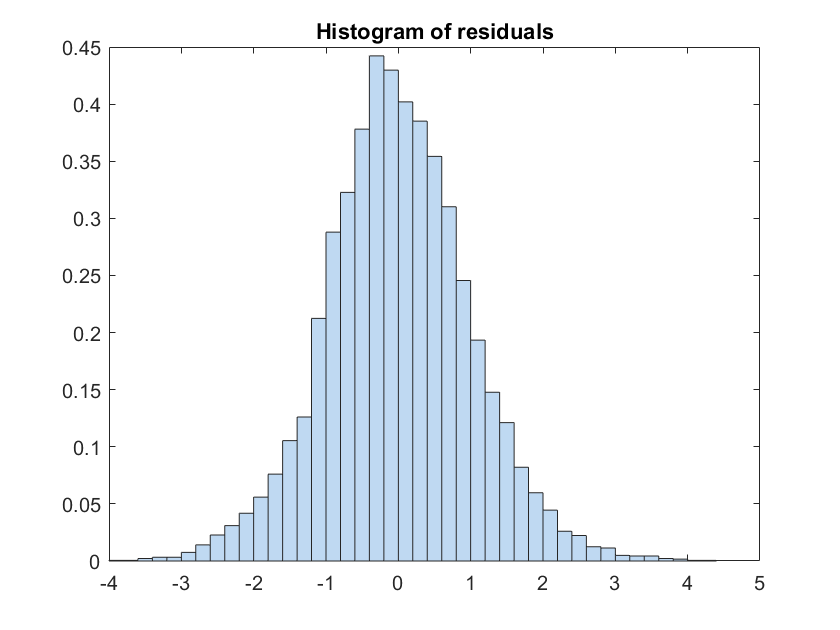


plotResiduals(glme,'histogram','ResidualType','Pearson')

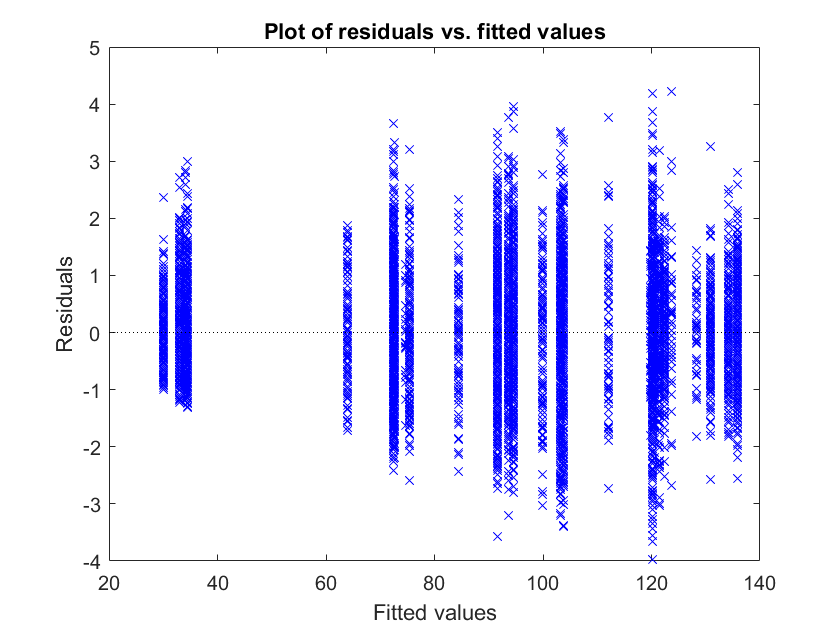

plotResiduals(glme,'fitted','ResidualType','Pearson')

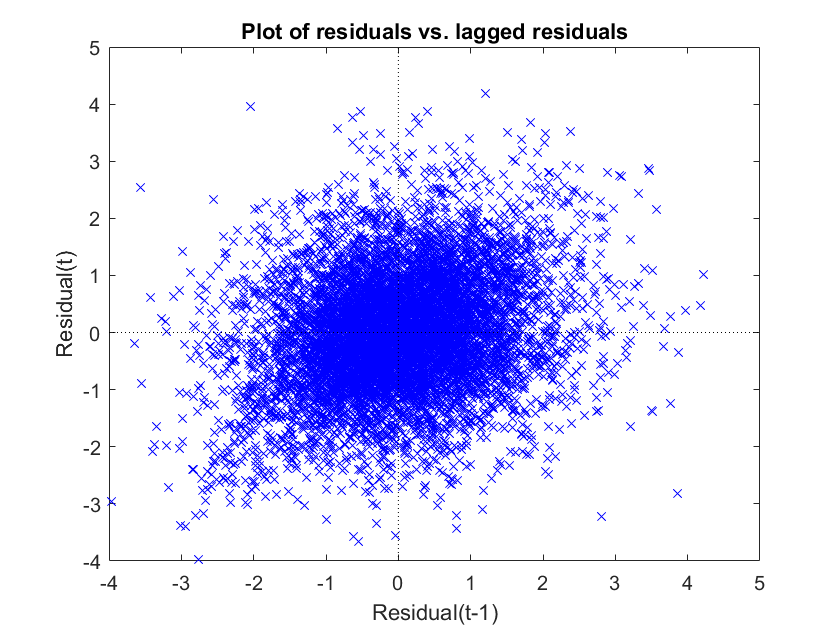

plotResiduals(glme,'lagged','ResidualType','Pearson')

tableBetaStim = table(anovaTotalMags',categorical(anovaType)',categorical(anovaNumStims)',categorical(anovaBetaSID)',...
    'VariableNames',{'Magnitude','Type','NumStims','SID'});
glme = fitglme(tableBetaStim,'Magnitude~NumStims+Type+(Type|SID)+(NumStims|SID)',...
    'Distribution','Normal','Link','Identity','FitMethod','Laplace','DummyVarCoding','effects')

glme = Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations            9204
    Fixed effects coefficients           8
    Random effects coefficients         63
    Covariance parameters               26
    Distribution                    Normal
    Link                            Identity
    FitMethod                       Laplace

Formula:
    Magnitude ~ 1 + Type + NumStims + (1 + Type | SID) + (1 + NumStims | SID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    81631    81874    -40782           81563   

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE         tStat        DF      pValue        Lower       Upper  
    '(Intercept)'                96.325     8.6431       11.145    9196    1.1596e-28      79.382     113.27
    'Type_0'                    -23.561     8.6359      -2.7282    9196

disp(glme)


Generalized linear mixed-effects model fit by ML

Model information:
    Number of observations            9204
    Fixed effects coefficients           8
    Random effects coefficients         63
    Covariance parameters               26
    Distribution                    Normal
    Link                            Identity
    FitMethod                       Laplace

Formula:
    Linear Mixed Formula with 3 predictors.

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    81631    81874    -40782           81563   

Fixed effects coefficients (95% CIs):
    Name                       Estimate    SE     
    '(Intercept)'                96.325     8.6431
    'Type_0'                    -23.561     8.6359
    'Type_180'                  -3.2726     12.569
    'Type_270'                 -0.70523     11.276
    'Type_90'                   0.86574     9.7337
    'NumStims_1<=Ct<=2'

anova(glme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                 FStat     DF1    DF2     pValue     
    '(Intercept)'         124.2    1      9196     1.1596e-28
    'Type'               362.63    4      9196    2.1253e-290
    'NumStims'           4.7997    3      9196      0.0024211


[psi,dispersion,stats] = covarianceParameters(glme)

psi = 2×1 cell array
    {5×5 double}
    {4×4 double}


dispersion = 409.2471

stats = 3×1 cell array
    {15×7 classreg.regr.lmeutils.titleddataset}
    {10×7 classreg.regr.lmeutils.titleddataset}
    { 1×5 classreg.regr.lmeutils.titleddataset}


psi

psi = 2×1 cell array
    {5×5 double}
    {4×4 double}


dispersion

dispersion = 409.2471

stats

stats = 3×1 cell array
    {15×7 classreg.regr.lmeutils.titleddataset}
    {10×7 classreg.regr.lmeutils.titleddataset}
    { 1×5 classreg.regr.lmeutils.titleddataset}
